% This notebook is a demonstration of the two models used in the Zika 2022
% paper https://www.biorxiv.org/content/10.1101/2022.04.01.483303v2 
% Author: Ondrej Zika


% Generate binary data 
nblocks = 6; % number of blocks
bltrials = 20; % number of trials in a phase
probs = [0.1 0.9]; % contingency levels of the two states
o =[];
for i = 1:nblocks
    o = [o binornd(1, probs(rem(i,2)+1), 1, bltrials)];
end

% Generate some data using the 1-state model (gradual data)
m1 = onestate_model([1,1,2,2,log(0.9)],o);

% Generate some data using the n-state model (switching model)
mN = nstate_model([0.1 0.1 3.5 4 2 log(0.99)], o);


#### Comparison between 1-state and n-state models

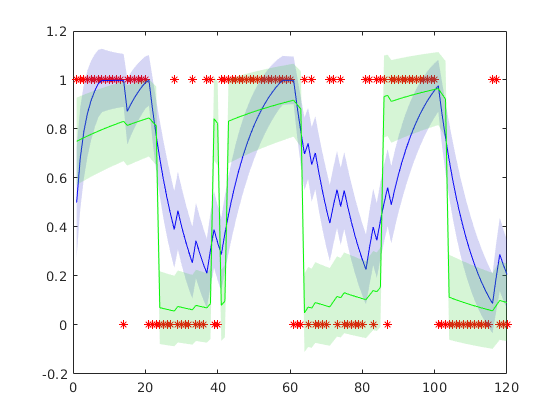

% plot the generated data 
f=figure;
plot(o, 'r*'); hold on 

% plot 1-state
plot(m1.Q, 'b'); m1.Q(length(m1.Q)) =[];
% shade thing to get a rough state uncertainty (1 SD) 
shade_area_bet_curves(1:numel(m1.Q), m1.Q-m1.U, m1.Q+m1.U, [0.2 0.2 0.8], 0.2);

% plot n-state
plot(mN.Q, 'g'); mN.Q(length(mN.Q)) =[];
shade_area_bet_curves(1:numel(mN.Q), mN.Q-mN.U, mN.Q+mN.U, [0.2 0.8 0.2], 0.2);

#### Fitting the n-state artificial data with n-state model

The model has a threshold parameter (eta) which makes fitting tricky, especially when using MCMC methods that assume smooth likelihood function. It should be fitted using derivative-free methods. Ideally, one fits it many times and takes the best fit. Using this strategy, the model and the parameters recover well.  

Here, I fit the model 5 times and take fit with lowest likelihood. 

% fit the n-state model to the n-state data

% get configuration for the nstate model
config_nstate_model; X=[]; err=[];
% specify data 
cfg.spec.data.probs = mN.Q;
for r =1:spec.noruns
X0=[]; % random starting values X0 or each fit
for i = 1:length(spec.limits(:,1))
    X0(i) = rand*(abs(spec.limits(i,1) - spec.limits(i,2))) + spec.limits(i,1);
end   
[X(r,1:length(X0)), err(r)] = bads(@model_error, X0, cfg.spec.limits(:,1)', cfg.spec.limits(:,2)', [], [], [], [], o, cfg.spec.data.probs, cfg);
end

Variables (index) internally transformed to log coordinates: [3 4 5].
Beginning optimization of a DETERMINISTIC objective fcn.

 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        0.769717               1                              Uncertainty test
     0           8       -0.401918               1            Initial mesh      
     1          14        -2.04709               1         Successful poll      Train
     2          16        -2.49695               1    Incremental search (ES-wcm)      
     2          19        -8.04557               1    Successful search (ES-wcm)      
     2          20        -24.5357               1    Successful search (ES-wcm)      
     2          31        -26.3309               1         Successful poll      
     3          34          -31.46               1    Successful search (ES-wcm)      
     3          36        -50.8512               1    Successful search (ES-wcm)      
   

% err is actually negative likelihood based on the beta distribution
% (summed across trials) 

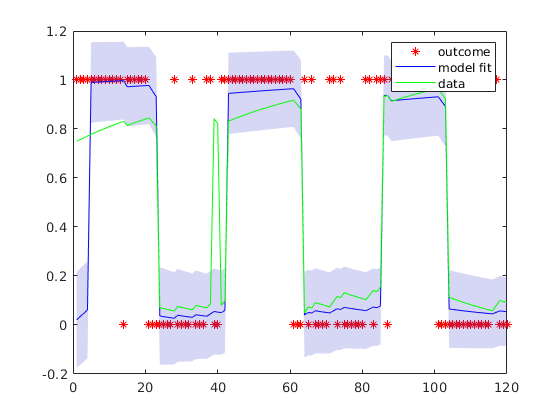

% take fit with lowest likelihood and plot
id=find(err==min(err));
mNstate = nstate_model(X(id,:),o);
% plot the generated data 
f=figure;
plot(o, 'r*'); hold on 
plot(mNstate.Q, 'b'); mNstate.Q(length(mNstate.Q)) =[];
% shade thing to get a rough state uncertainty (1 SD) 
shade_area_bet_curves(1:numel(mNstate.Q), mNstate.Q-mNstate.U, mNstate.Q+mNstate.U, [0.2 0.2 0.8], 0.2);
plot(cfg.spec.data.probs, 'g');
legend({'outcome', 'model fit', 'data'});